# Chapter 4. Regression and Prediction: P162 - 219

clear; close all;
dataDir = "../psds_data";
dataList = dir(dataDir);
dataList.name

ans = '.'

ans = '..'

ans = '762609057_112015_3429_airline_delay_causes.csv'

ans = 'County_Zhvi_AllHomes.csv'

ans = 'LungDisease.csv'

ans = 'airline_stats.csv'

ans = 'click_rates.csv'

ans = 'dfw_airline.csv'

ans = 'four_sessions.csv'

ans = 'full_train_set.csv'

ans = 'house_sales.csv'

ans = 'imanishi_data.csv'

ans = 'kc_tax.csv'

ans = 'lc_loans.csv'

ans = 'loan200.csv'

ans = 'loan3000.csv'

ans = 'loan_data.csv'

ans = 'loans_income.csv'

ans = 'sp500_data.csv'

ans = 'sp500_sectors.csv'

ans = 'state.csv'

ans = 'web_page_data.csv'

## Simple Linear Regression

### The regression Equation


$$Y = b_0 + b_1X$$


lung = readtable(fullfile(dataDir, "LungDisease.csv"));
head(lung)

ans = 8×2 table
    PEFR    Exposure
    ____    ________

    390        0    
    410        0    
    430        0    
    460        0    
    420        1    
    280        2    
    420        2    
    520        2    


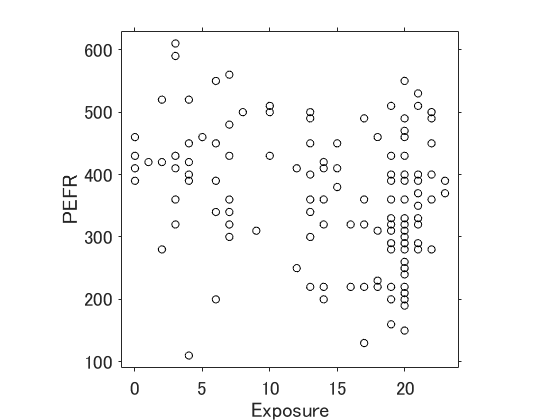

sc1 = scatter(lung.Exposure, lung.PEFR,'ok', 'SizeData', 30);
ax1 = sc1.Parent;
axis(ax1, 'square');
xlabel(ax1, "Exposure");
ylabel(ax1, "PEFR");
%
ax1.XTick = [0 5 10 15 20];
ax1.YTick = [100 200 300 400 500 600];
ax1.XLim = [-1, 24];
ax1.YLim = [90, 630];
ax1.FontSize = 14;
ax1.TickDir = "out";
ax1.Color = "none";
ax1.Box = "on";


$$\text{PEFR} = b_0 + b_1\;\text{Exposure}$$


model = fitlm(lung, "PEFR~Exposure");
disp(model);

線形回帰モデル: 
    PEFR ~ 1 + Exposure

推定された係数: 
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     424.58     20.796     20.417    7.5122e-41
    Exposure       -4.1846      1.325    -3.1582     0.0020084


観測数: 122、誤差の自由度: 120
平方根平均二乗誤差: 101
決定係数: 0.0767、自由度調整済み決定係数: 0.069
F 統計量 - 定数モデルとの比較: 9.97、p 値は 0.00201 です


### Fitted Values and Residuals

The error is denoted by $e_i
$ and the fitted value $\hat{Y}_i$, and the residuals $\hat{e}_i$ respectively: 


$$Y_i = b_0 + b_1 X_i + e_i\\
\hat{y}_i = \hat{b}_0 + \hat{b}_1X_i\\
\hat{e}_i = Y_i-\hat{Y}_i$$


fitted and residual:

fitted = model.Fitted;
resid = model.Residuals;

Plotting them together:

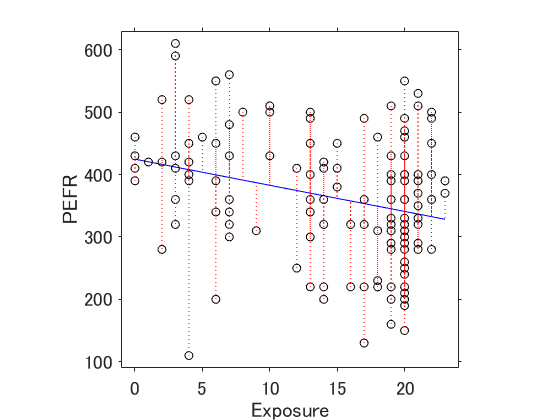

p2 = plot(lung.Exposure, fitted, '-b',...
    lung.Exposure, lung.PEFR, 'ok', "MarkerSize",6);
ax2 = p2.Parent;
axis(ax2,"square");
xlabel(ax2, "Exposure");
ylabel(ax2, "PEFR");
%
ax2.XTick = [0 5 10 15 20];
ax2.YTick = [100 200 300 400 500 600];
ax2.XLim = [-1, 24];
ax2.YLim = [90, 630];
ax2.FontSize = 14;
ax2.TickDir = "out";
ax2.Color = "none";
ax2.Box = "on";
%
hold on;
for i=1:length(lung.PEFR)
    plot([lung.Exposure(i), lung.Exposure(i)], [lung.PEFR(i), fitted(i)],'r:');
end
hold off;

### Least Squares

Residual sum of squares - RSS


$$\begin{array}{rcl}
RSS &=& \sum_{i=1}^n (Y_i-\hat{Y}_i)^2\\
       &=& \sum_{i=1}^n (Y_i-\hat{b}_0-\hat{b}_1X_i)^2
\end{array}$$


## Multiple Linear Regression


$$Y = b_0 + b_1 X_1 + \cdots + b_pX_p + e$$


The fitted values are given by:


$$\hat{Y}_i = \hat{b}_0 + \hat{b}_1 X_1 + \cdots + \hat{b}_pX_{p,i}$$


### Example: King County Housing Data

% データ読み込みオプション
opts = delimitedTextImportOptions("NumVariables", 23);

% 範囲と区切り記号の指定
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% 列名と型の指定
% Note that: SaleDateは無かったので加筆
opts.VariableNames = ["DocumentDate","SaleDate", "SalePrice", "PropertyID", "PropertyType", "ym", "zhvi_px", "zhvi_idx", "AdjSalePrice", "NbrLivingUnits", "SqFtLot", "SqFtTotLiving", "SqFtFinBasement", "Bathrooms", "Bedrooms", "BldgGrade", "YrBuilt", "YrRenovated", "TrafficNoise", "LandVal", "ImpsVal", "ZipCode", "NewConstruction"];
opts.VariableTypes = ["double", "datetime", "double", "double", "categorical", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["PropertyType", "NewConstruction"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "SaleDate", "InputFormat", "yyyy-MM-dd");
opts = setvaropts(opts, "ym", "InputFormat", "yyyy-MM-dd");

% データ読み込み
house = readtable(fullfile(dataDir, "house_sales.csv"), opts);
head(house(:,{'AdjSalePrice','SqFtTotLiving','SqFtLot','Bathrooms', 'Bedrooms', 'BldgGrade'}))

ans = 8×6 table
    AdjSalePrice    SqFtTotLiving    SqFtLot    Bathrooms    Bedrooms    BldgGrade
    ____________    _____________    _______    _________    ________    _________

     3.0081e+05         2400           9373          3          6            7    
     1.0762e+06         3764          20156       3.75          4           10    
     7.6181e+05         2060          26036       1.75          4            8    
     4.4207e+05         3200           8618       3.75          5            7    
     2.9707e+05         1720           8620       1.75          4            7    
     4.1178e+05          930           1012        1.5          2            8    
     3.8079e+05         1750          34465        1.5          3            8    
     3.4949e+05         1860          14659       1.75          4            7    


Establish a model that drops the records with missing values:

% Remove missing records from the table
%house_cleaned = rmmissing(house,2);
house_cleaned = removevars(house, {'ZipCode', 'ym', 'SaleDate', 'PropertyID', 'SalePrice','ImpsVal', 'DocumentDate','zhvi_px','zhvi_idx', 'TrafficNoise', 'LandVal'});

% Model
house_lm = fitlm(house_cleaned, "AdjSalePrice ~ SqFtTotLiving + SqFtLot + Bathrooms + Bedrooms + BldgGrade");

### Assessing the Model P175

disp(house_lm);

線形回帰モデル: 
    AdjSalePrice ~ 1 + SqFtLot + SqFtTotLiving + Bathrooms + Bedrooms + BldgGrade

推定された係数: 
                      Estimate         SE        tStat        pValue   
                     ___________    ________    ________    ___________

    (Intercept)      -5.2192e+05       15651     -33.349    4.2325e-238
    SqFtLot            -0.060506    0.061181    -0.98896        0.32269
    SqFtTotLiving         228.83      3.8984      58.699              0
    Bathrooms             -19438      3625.2     -5.3619     8.3151e-08
    Bedrooms              -47781      2489.4     -19.194     1.8564e-81
    BldgGrade         1.0612e+05      2396.1      44.287              0


観測数: 22689、誤差の自由度: 22683
平方根平均二乗誤差: 2.61e+05
決定係数: 0.541、自由度調整済み決定係数: 0.541
F 統計量 - 定数モデルとの比較: 5.34e+03、p 値は 0 です


Residual:

summary(house_lm.Residuals);

Variables:

    Raw: 22689×1 double

        Values:

            Min       -1.1995e+06
            Median         -20982
            Max         9.473e+06

    Pearson: 22689×1 double

        Values:

            Min         -4.5915
            Median    -0.080315
            Max          36.261

    Studentized: 22689×1 double

        Values:

            Min         -4.5963
            Median    -0.080321
            Max          37.395

    Standardized: 22689×1 double

        Values:

            Min         -4.5943
            Median    -0.080323
            Max          36.294



Residual - 1Q, Median, 3Q:

quantile(house_lm.Residuals{:,"Raw"},3)

ans = 	1.0e+05 *

   -1.1889   -0.2098    0.8742


### Cross-Validation

k-fold cross-validation:

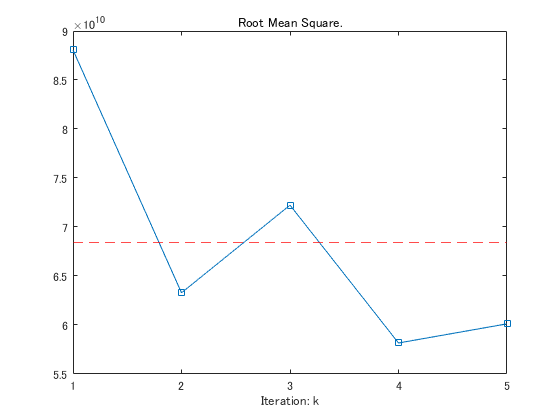

k = 5;
c = cvpartition(size(house_cleaned,1), 'KFold', k);
mse = zeros(1,k);

for i=1:k
    idx_train = training(c,i);
    idx_test = test(c,i);
    
    trainTable = house_cleaned(idx_train,:);
    testTable = house_cleaned(idx_test,:);
    
    mdl = fitlm(trainTable, "AdjSalePrice ~ SqFtTotLiving + SqFtLot + Bathrooms + Bedrooms + BldgGrade");
    yfit = feval(mdl,testTable);
    mse(i) = mean((yfit-testTable.AdjSalePrice).^2);
end

% visualize
plot(1:k, mse,'s-');
yline(mean(mse),'r--');
title("Root Mean Square.");
xticks(1:5); xlabel("Iteration: k")

### Model Selection and Stepwise Regression

%house_full = fitlm(house_cleaned, "AdjSalePrice ~ SqFtTotLiving + SqFtLot + Bathrooms + Bedrooms + BldgGrade + PropertyType + NbrLivingUnits + SqFtFinBasement + YrBuilt + YrRenovated + NewConstruction");

#### stepAIC


$$AIC = 2P + n\log(RSS/n) \\
\text{where} \quad p: \text{the number of variables}$$


step = stepwiseglm(house_cleaned, "linear","ResponseVar","AdjSalePrice","upper","linear","Criterion","aic", 'Verbose', 2);

   追加する候補項はありません
   PropertyType を削除する AIC 内の変化 は 69.1683 です
   NbrLivingUnits を削除する AIC 内の変化 は -1.8922 です
   SqFtLot を削除する AIC 内の変化 は -0.23252 です
   SqFtTotLiving を削除する AIC 内の変化 は 2100.4576 です
   SqFtFinBasement を削除する AIC 内の変化 は 0.3223 です
   Bathrooms を削除する AIC 内の変化 は 124.4259 です
   Bedrooms を削除する AIC 内の変化 は 462.3087 です
   BldgGrade を削除する AIC 内の変化 は 2960.9456 です
   YrBuilt を削除する AIC 内の変化 は 2045.8563 です
   YrRenovated を削除する AIC 内の変化 は -1.5875 です
   NewConstruction を削除する AIC 内の変化 は -1.8308 です
1. NbrLivingUnits, AIC = 6.2758e+05 を削除しています
   追加する候補項はありません
   PropertyType を削除する AIC 内の変化 は 69.3192 です
   SqFtLot を削除する AIC 内の変化 は -0.22025 です
   SqFtTotLiving を削除する AIC 内の変化 は 2103.9601 です
   SqFtFinBasement を削除する AIC 内の変化 は 0.28859 です
   Bathrooms を削除する AIC 内の変化 は 126.372 です
   Bedrooms を削除する AIC 内の変化 は 463.3013 です
   BldgGrade を削除する AIC 内の変化 は 2979.4556 です
   YrBuilt を削除する AIC 内の変化 は 2062.021 です
   YrRenovated を削除する AIC 内の変化 は -1.5782 です
   NewConstruction を削除する AIC 内の変化 は -1.8274 です
2. NewCo

disp(step)

一般化線形回帰モデル:
    AdjSalePrice ~ [7 予測子に 8 の項をもつ線形式]
     分布は Normal です

推定された係数: 
                                   Estimate         SE         tStat       pValue  
                                  __________    __________    _______    __________

    (Intercept)                   6.1777e+06    1.3549e+05     45.595             0
    PropertyType_Single Family         22855         15800     1.4465       0.14804
    PropertyType_Townhouse             84379         17595     4.7956     1.632e-06
    SqFtTotLiving                     199.27        4.1713     47.773             0
    SqFtFinBasement                   7.0322        4.6035     1.5276       0.12664
    Bathrooms                          42403        3747.5     11.315    1.3252e-29
    Bedrooms                          -51975          2386    -21.784    3.884e-104
    BldgGrade                     1.3718e+05        2427.3     56.516             0
    YrBuilt                          -3564.9        71.262    -50.026         

The variables that are taken away from the list by the calculation above are: SqFtLot, NbrLivingUnits, YrRenovated and Newconstruction. This  matches with the result obtained by R.

### Weighted Regression P180

- Inverse-variance weighting: 観測の精度が異なる場合

- データが集められた形で解析をする場合

`DocumentDate`をWeightとして採用 (古いと信頼性が低いので)

house_cleaned.Weight = year(house.ym) -2005;

回帰

house_wt = fitlm(house_cleaned,"AdjSalePrice ~ SqFtTotLiving + SqFtLot + Bathrooms + Bedrooms + BldgGrade",...
    "Weights", house_cleaned.Weight);

比較

disp(house_lm);

線形回帰モデル: 
    AdjSalePrice ~ 1 + SqFtLot + SqFtTotLiving + Bathrooms + Bedrooms + BldgGrade

推定された係数: 
                      Estimate         SE        tStat        pValue   
                     ___________    ________    ________    ___________

    (Intercept)      -5.2192e+05       15651     -33.349    4.2325e-238
    SqFtLot            -0.060506    0.061181    -0.98896        0.32269
    SqFtTotLiving         228.83      3.8984      58.699              0
    Bathrooms             -19438      3625.2     -5.3619     8.3151e-08
    Bedrooms              -47781      2489.4     -19.194     1.8564e-81
    BldgGrade         1.0612e+05      2396.1      44.287              0


観測数: 22689、誤差の自由度: 22683
平方根平均二乗誤差: 2.61e+05
決定係数: 0.541、自由度調整済み決定係数: 0.541
F 統計量 - 定数モデルとの比較: 5.34e+03、p 値は 0 です


disp(house_wt);

線形回帰モデル: 
    AdjSalePrice ~ 1 + SqFtLot + SqFtTotLiving + Bathrooms + Bedrooms + BldgGrade

推定された係数: 
                      Estimate         SE        tStat       pValue   
                     ___________    ________    _______    ___________

    (Intercept)      -5.8427e+05       16722    -34.939    1.5082e-260
    SqFtLot             -0.29243    0.060442    -4.8382     1.3189e-06
    SqFtTotLiving         245.02      4.1766     58.665              0
    Bathrooms             -26079      3875.6     -6.729     1.7492e-11
    Bedrooms              -53625      2668.2    -20.098     4.6121e-89
    BldgGrade         1.1526e+05      2551.3     45.176              0


観測数: 22689、誤差の自由度: 22683
平方根平均二乗誤差: 4.79e+05
決定係数: 0.539、自由度調整済み決定係数: 0.539
F 統計量 - 定数モデルとの比較: 5.31e+03、p 値は 0 です


## Prediction Using Regression P181

## Factor Variables in Regression P 184